# MIMO TRANSMISSION PROJECT:

**By Malavika Venkatanarayanan**

The aim of this project is to show the effect of different MCS and streams in a MIMO System.

The resources used in the making of this project are :Wireless Exercises and labs.

MIMO (Multiple-Input Multiple-Output) and beamforming are advanced  techniques used in wireless communication systems to enhance data  transmission and reception. MIMO involves the use of multiple antennas  at both the transmitting and receiving ends of a wireless link. By  exploiting the spatial dimension, MIMO enables multiple data streams to  be transmitted simultaneously, effectively increasing the capacity and  improving the overall performance of the wireless system. Beamforming,  on the other hand, is a signal processing technique used in conjunction  with MIMO to focus the transmitted signal in a specific direction  towards the intended receiver. This allows for improved signal strength, reduced interference, and increased coverage range. By steering the  signal towards the desired receiver and suppressing unwanted signals,  beamforming significantly enhances the quality and reliability of  wireless communication, particularly in environments with high  interference or multipath propagation. Together, MIMO and beamforming  play a vital role in maximizing spectral efficiency and improving the  overall user experience in wireless networks.

**LOADING THE FILE:**

clear all;
load roomPathData.mat

**PARAMETERS:**

LinkStates = pathData.linkState;
LOS = find(LinkStates==1); %indices for LOS links
NLOS = find(LinkStates==2); %Used later

rxNum = LOS(randi([1,length(LOS)])); %randomly Selecting an RX number from LOS indices

txPos = pathData.txPos; %Getting tx Position

rxPos = pathData.rxPos(rxNum,:); %Getting rx Position

**PLOTTING TRANSMITTER AND RECEIVER POSITION:**

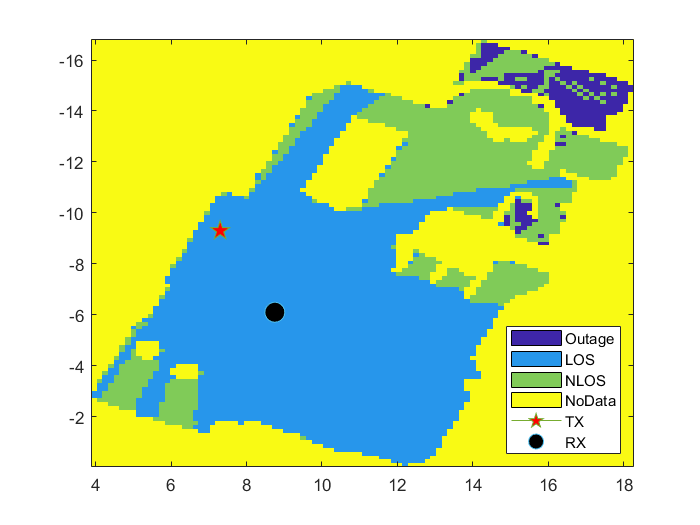

clf;
noDataValue = 3;  % Use this value for positions with no data

% Legend labels
legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Create a mapper for plotting
mapper = DataMapper(pathData.rxPos, pathData.posStep);

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

% Overlay the TX position
txPos = pathData.txPos;
plot(txPos(1), txPos(2), '-p', 'MarkerSize', 12,'MarkerFaceColor','red', 'DisplayName', 'TX');
plot(pathData.rxPos(rxNum,1), pathData.rxPos(rxNum,2), "o", ...
    'MarkerSize', 12,'MarkerFaceColor','black', 'DisplayName', 'RX');
hold off;


% Display the legend
legend('Location', 'SouthEast');


npaths = pathData.npaths(rxNum,:); %Number of paths
gain = pathData.gain(rxNum,:); %Gain of each path
dly = pathData.dly(rxNum,:); %Delay of each path


aoaAz = pathData.aoaAz(rxNum,:)';
aoaEl = pathData.aoaEl(rxNum,:)';
aodAz = pathData.aodAz(rxNum,:)';
aodEl = pathData.aodEl(rxNum,:)';

Next, we calculate the vector from the transmitter to the receiver (trVec) by subtracting the transmitter position (txPos) from the receiver position (rxPos). The apostrophe ('), in this case, denotes the transpose operation.

The next line of code normalizes the trVec vector by dividing it by its norm. Normalizing a vector scales it to have a length of 1 while preserving its direction.

The variable zvec represents a vector pointing towards the positive z-direction. It is a default orientation for the antenna elements.

The subsequent line calculates the tiltAx vector by taking the cross product of zvec and [trVec;0]. The cross product of two vectors results in a vector that is perpendicular to both of them. In this case, tiltAx represents the axis of rotation required to align the antenna elements towards the receiver.

The variable tiltAngle is set to 90, indicating that the tiltAx, trVec, and zvec vectors are mutually orthogonal or perpendicular to each other.

trVec = rxPos' - txPos; 
trVec = trVec/norm(trVec);
zvec = [0,0,1]';
tiltAx = cross(zvec,[trVec;0]);
tiltAngle = 90; 

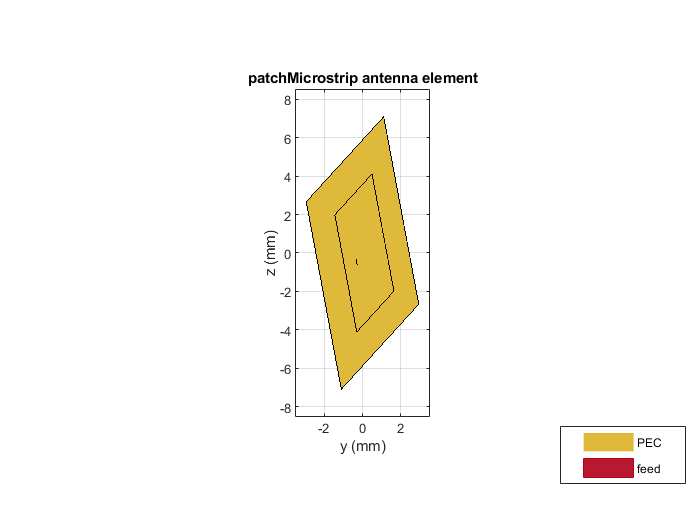

fc = pathData.fc; %Carrier Frequency
elemTx = design(patchMicrostrip, fc); %Tx antenna element
elemTx.Tilt = 90; 
elemTx.TiltAxis = tiltAx';

elemRx = design(patchMicrostrip, fc); %Rx antenna element
elemRx.Tilt = 90; 
elemRx.TiltAxis = -tiltAx';

%Displaying Antennas
elemTx.show()
view(90,0);

nantgNB = [4,4]; % 16 Antennas at transmitter
nantUE = 8; % 8 Antennas at receiver

lambda = physconst('LightSpeed')/fc; %Wavelength
dsep = 0.5*lambda;   % element spacing

%transmitter array
arrgNB = phased.URA(nantgNB,dsep,"ArrayNormal","x");  
%ULA for receiver
arrUE = phased.ULA(nantUE,dsep,"ArrayAxis","y");

**VIEWING THE ANTENNA ARRAYS**

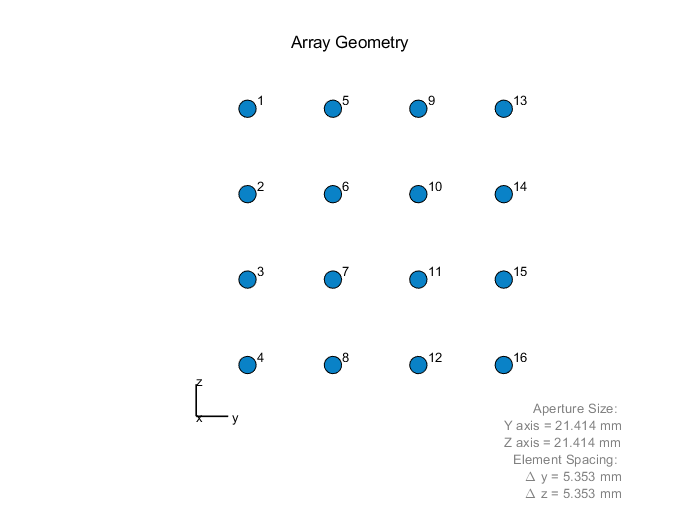

viewArray(arrgNB,'ShowTaper',true,'ShowIndex','All')%transmitter array

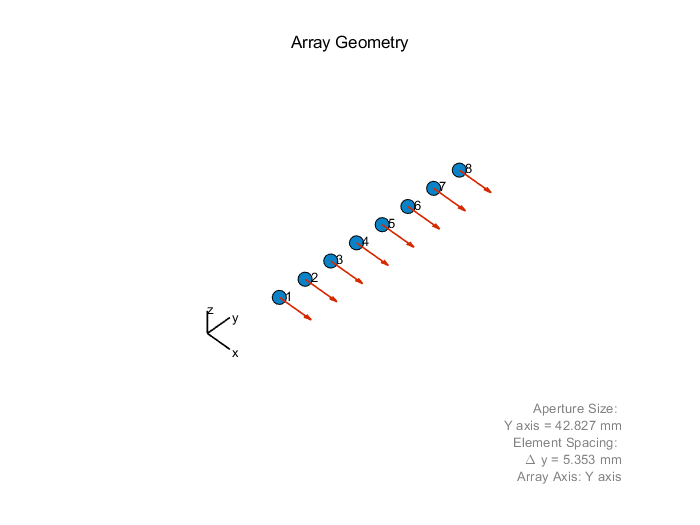


viewArray(arrUE,'ShowNormals',true,'ShowIndex','All');%Receiver array

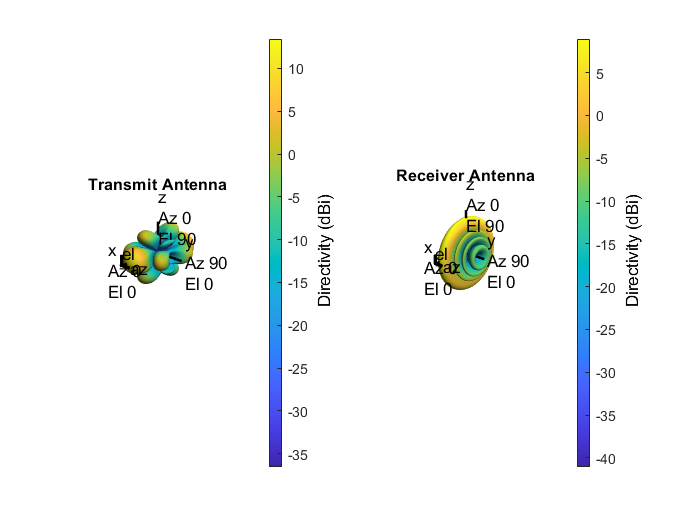

%antenn pattern
subplot(1,2,1)
arrgNB.pattern(fc);
title('Transmit Antenna')
subplot(1,2,2);
arrUE.pattern(fc);
title('Receiver Antenna')


arrPlatformgNB = ArrayPlatform('elem', elemTx, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', elemRx, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

**VISUALIZING STEERING VECTOR AND GAIN:**

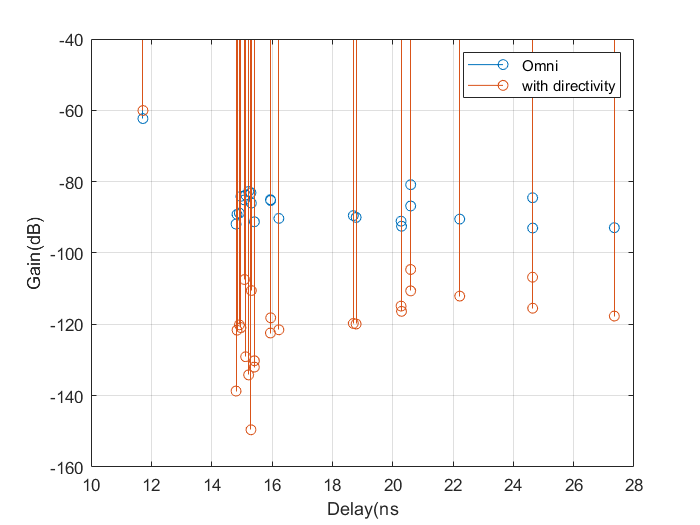

[svTx, elemGainTx] = arrPlatformgNB.step(aodAz, aodEl);
[svRx, elemGainRx] = arrPlatformUE.step(aoaAz, aoaEl);
%Element gain
gainElem =  gain + elemGainTx + elemGainRx;


%array gain calculation
[~,im] = max(gainElem);
wtx = conj(svTx(:,im));
wtx = wtx / norm(wtx);
wrx = conj(svRx(:,im));
wrx = wrx / norm(wrx);
arrGainTx = 10*log10( abs(sum(wtx.*svTx, 1)).^2 );
arrGainRx = 10*log10( abs(sum(wrx.*svRx, 1)).^2 );
%array gain
gainArr = gain + arrGainTx + arrGainRx;
clf;
stem(dly/1e-9,[gain;gainArr]','BaseValue', -40);
grid on;
xlabel('Delay(ns')
ylabel('Gain(dB)')
legend('Omni', 'with directivity');

**CREATING THE TRANSMITTOR**

I have used the NRgNBTxFD file from the previous lab to create the transmittor.

Modulation = '16QAM';
targetCodeRate = 340/1024;
SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB
carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);
pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'PTRS', nrPDSCHPTRSConfig(),...
    'NumLayers', 1);
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

**CREATING THE  OFDM MIMO CHANNEL:**

The  FDMIMOChan is used form the lab exercises. I have tweaked it a bit for precoding.


fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc);

frameNum = 0;
slotNum = 0;
[chanGrid, Q] = fdchan.step(frameNum, slotNum); 


%Here Q is the Q = inv(alpha*H'*H+eye(ntx));

nStreams = 2; %no of streams

[txGrid,Fprecoder] = tx.step(nStreams,Q);
%The output txGrid is the precoded inside, Tx divides unit power equally
%across nstreams so E||x||^2=1 where x is a vector of size nstreams x 1


G = pagemtimes(chanGrid,Fprecoder); 
AvgSNR = 10; 
noiseVar = sum(mean(abs(G).^2,[3,4]),'all')/db2pow(AvgSNR)/nantUE/nStreams;

%Now we pass txGrid through the channel and add noise to obtain received
%grid txGrid
rxGridNoNoise = pagemtimes(chanGrid,txGrid);
rxGrid = rxGridNoNoise + sqrt(noiseVar/2)*(randn(size(rxGridNoNoise))+1j*randn(size(rxGridNoNoise))); %Adding  noise


rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
rx.step(rxGrid, G, noiseVar,nStreams); %Demodulation

errtot=0;
tot=0;

rxBits = rx.rxBits;
txBits = tx.txBits;

CorrectBits = length(find(rxBits == txBits));
ErrorBits = length(find(rxBits ~= txBits));
%total no of bits
TotalBits = length(txBits);
%no of error bits
errtot = errtot + ErrorBits;
tot = tot+ TotalBits

tot = 23056

%error rate
error=errtot/tot;
fprintf('%d,%d',CorrectBits,TotalBits)

23036,23056

fprintf("errtot/totSubTot= %d",error);

errtot/totSubTot= 8.674532e-04

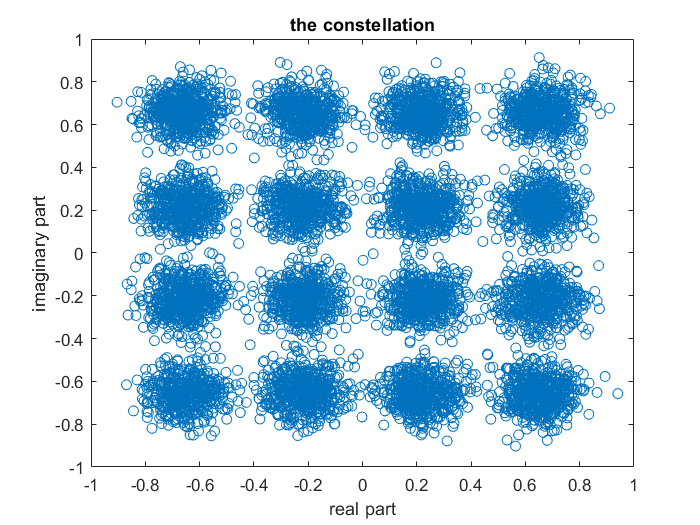

clf
plot(real(rx.pdschEq),imag(rx.pdschEq),'o')
title("the constellation")
xlabel("real part")
ylabel("imaginary part")

**TRYING OUT FOR DIFFERENT STREAMS AND MCS**:

Now we do the same thing we have done above for different mcs and streams.

nStreamsVec = [1,2,3]; 
Modulation = '16QAM';
target = [790,553,616]/1024;
err = zeros(length(target),length(nStreamsVec));

for j=1:length(target)
    targetCodeRate = target(j);
    pdschConfig = nrPDSCHConfig(...
        'Modulation', Modulation, ...
        'PRBSet', (0:NRB-1), ...
        'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
        'PTRS', nrPDSCHPTRSConfig(),...
        'NumLayers', 1);


    nStreamsVec = [1,2,3]; 
    for i=1:length(nStreamsVec)
        errSubToT=0;
        totSubTot=0;
        for k=1:10
            tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
            nStreams=nStreamsVec(i);
            [txGrid,Fprecoder] = tx.step(nStreams,Q);
            G = pagemtimes(chanGrid,Fprecoder); 
            AvgSNR = 20;
            noiseVar = sum(mean(abs(G).^2,[3,4]),'all')/db2pow(AvgSNR)/nantUE/nStreams;

            
            rxGridNoNoise = pagemtimes(chanGrid,txGrid);
            rxGrid = rxGridNoNoise + sqrt(noiseVar/2)*(randn(size(rxGridNoNoise))+1j*randn(size(rxGridNoNoise)));
            rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
            rx.step(rxGrid, G, noiseVar,nStreams); 
            rxBits = rx.rxBits;
            txBits = tx.txBits;
            ErrorBits = length(find(rxBits ~= txBits));
            TotalBits = length(txBits);
            errSubTot = errSubToT + ErrorBits;
            totSubTot = totSubTot + TotalBits;
        end
        err(j,i)=errSubTot/totSubTot;       
    end
end

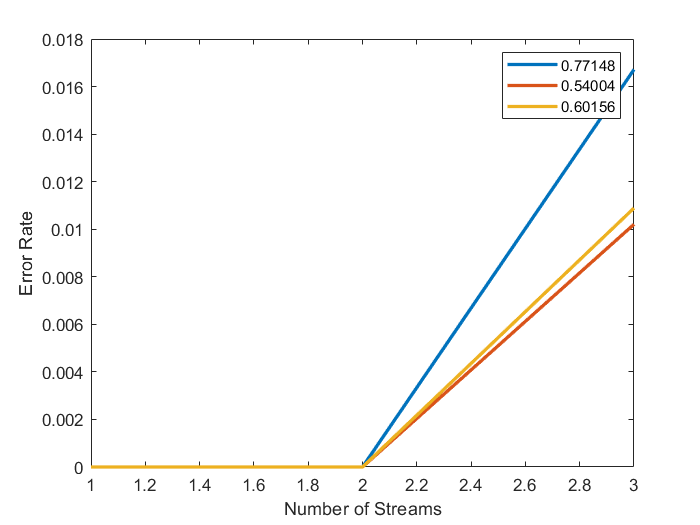


%PLOTTONG

clf;
for j=1:length(target)
    targetCodeRate = target(j);
    plot(nStreamsVec,err(j,:),'LineWidth',2);
    hold on;
    xlabel('Number of Streams')
    ylabel('Error Rate')
   
end
legend(string(target));

We see here that the error rate: is increasing with the increase in no of streams. Why is that?

Well.As the number of streams increases, there can be a higher probability of interference between the streams.The presence of interference can degrade the quality of individual streams, leading to an increased error rate.

we also notice that with an increase in mcs, the error rate incerases.As the MCS level increases, the modulation scheme becomes more sensitive to variations in the channel conditions. Higher-order modulation  schemes typically have narrow decision boundaries between symbol  points, making them more susceptible to small changes in the received  signal caused by noise, fading, or interference. Therefore, even small  deviations or disturbances in the channel can lead to higher error  rates.

I have used only three streams and three mcs for testing here. You can use any number to test it properly for other cnoditions.